# 'plot' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### *Povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'plot.pov', 'image_file', 'plot.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 35, 'location', [0 0 50], 'look_at', [0 0 0], 'type', 'orthographic');
    
    % Light
    pl.light('location', [0 0 50],   'color', [0.7 0.7 0.7], 'shadowless', true);
    pl.light('location', [50 50 50], 'color', [0.9 0.9 0.9]);
    
    % Axis
    tex_yellow = pl.declare("tex_axis_yellow", pl.texture('pigment', [2.0 2.0 0.0]));
    tex_gray   = pl.declare("tex_axis_gray",   pl.texture('pigment', [0.7 0.7 0.7]));
    pl.axis('length', [11 11 0], 'radius', 0.08, 'tex_common', tex_gray, 'tex_x', tex_yellow, 'tex_y', tex_yellow);
    
    % Background
    tex_back = pl.declare("tex_back",  pl.texture('pigment', [0.2 0.2 0.2]));
    pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_back);
    
    % Grid
    tex_grid = pl.declare("tex_grid",  pl.texture('pigment', [0.8 0.8 0.8]));
    pl.grid('texture', tex_grid, 'width', 20, 'height', 20, 'radius', 0.05 , 'rotate', [90 0  0]);
    
    % Plot
    pl.plot('name', 'fgreen', 'funcion', '4 * sin(X * pi/2) * ln(X)', ...
             'min_x', 0, 'max_x', 8, 'color', [0 0.8 0], ...
             'width', 0.1, 'translate', [0 0 0.1]);
    
    pl.plot('name', 'fyellow', 'funcion', 'sin(X * pi/2) * ln(-X)', ...
             'min_x', -8, 'max_x', 0, 'color', [0.25 0.38 1.5], ...
             'width', 0.1, 'translate', [0 0 0.1]);
    
    pl.plot('name', 'fred', 'funcion', 'X * X * X / 12', ...
             'min_x', -4.9, 'max_x', 4.9, 'color', [1.5 0.25 0.38], ...
             'width', 0.1, 'translate', [0 0 0.1]);
pl.scene_end();

#### Render and display

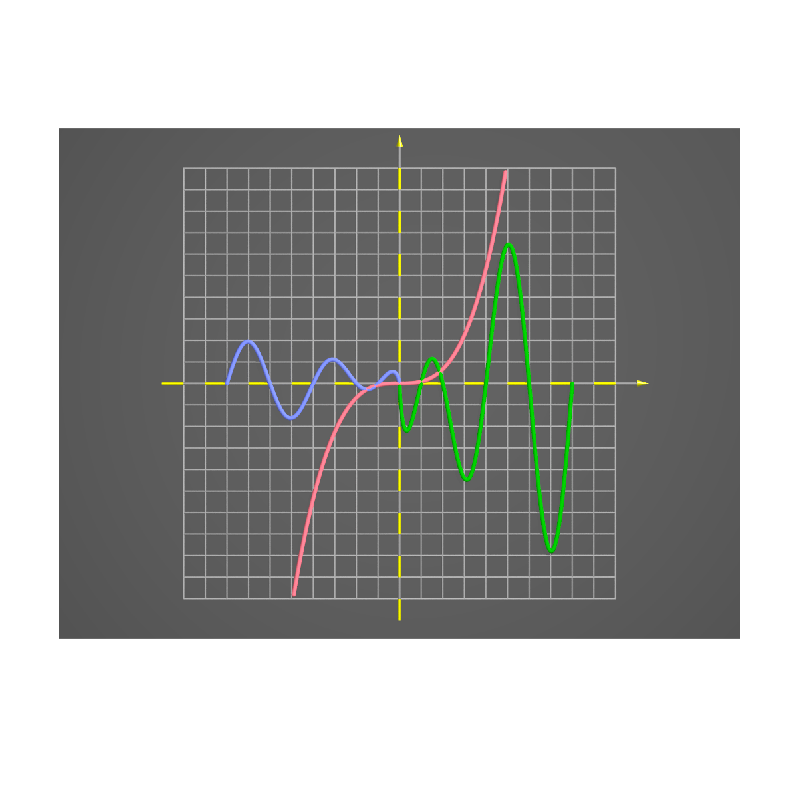

image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 4.977099 seconds.
